% setting
folder = 'C:\Users\bear\Desktop\figure 4';  
filename = 'crop_250'; % no need '_c{i}.tif'
outname_temp = 'crop_vessel_temp';  
outname = 'crop_vessel';
outname_final = 'crop_distance';
extension = '.tif';
num_channel = 2;
plane = 230;

multichannel = import4d(folder, filename, extension, num_channel);

Finished importing channel 1
Finished importing channel 2


nucleus = multichannel(:, :, :, 1);
cellular = multichannel(:, :, :, 2);

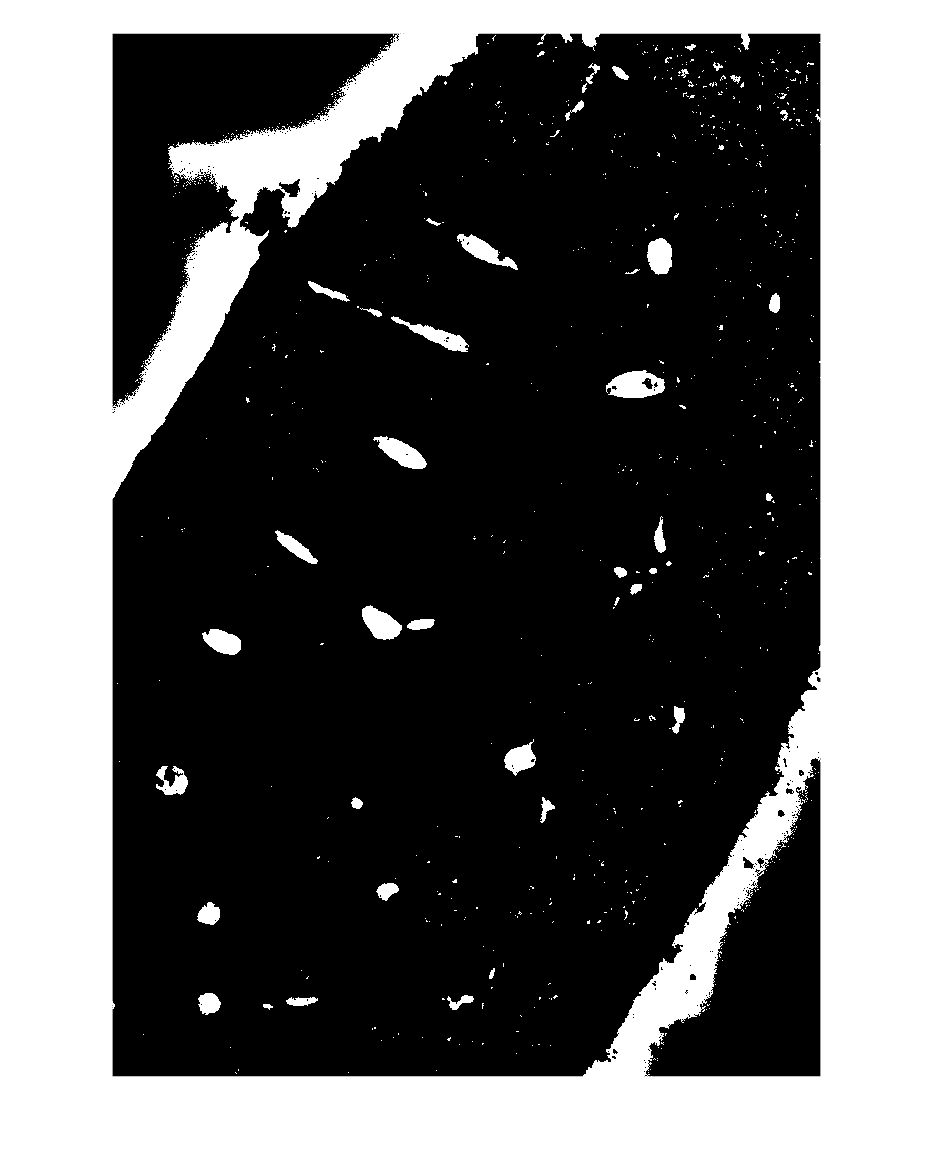

vessel_mask = ~imbinarize(cellular, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.2);
imshow(vessel_mask(:,:,plane));

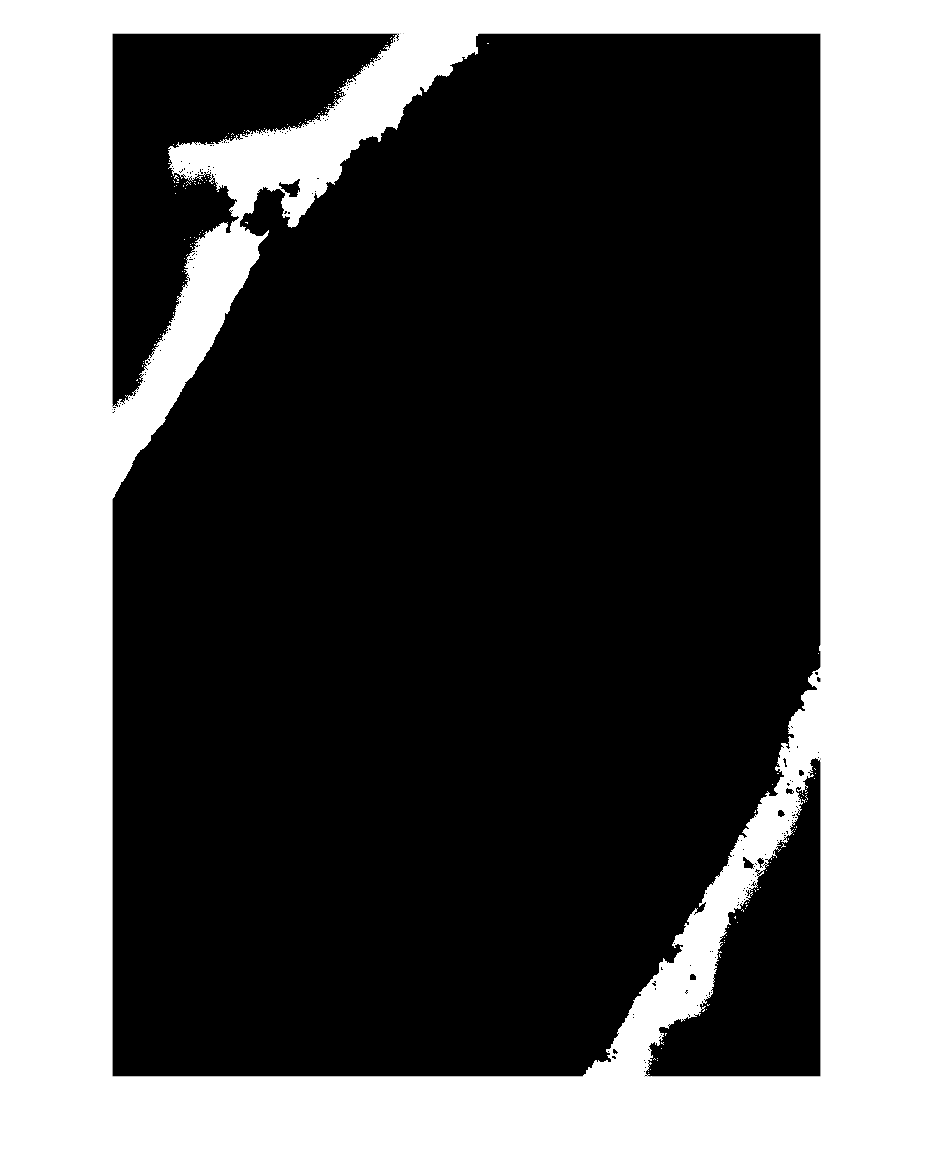

% isolate edge
temp_mask = vessel_mask;
[L, num] = bwlabeln(temp_mask);
component_sizes = histcounts(L(L>0), 1:num+1);
[sorted_sizes, sorted_indices] = sort(component_sizes, 'descend');
num_large_mask = 2;
edge_mask = zeros(size(L), 'like', L);
for i = 1:num_large_mask
    edge_mask = edge_mask | (L == sorted_indices(i));
end
imshow(edge_mask(:,:,plane));

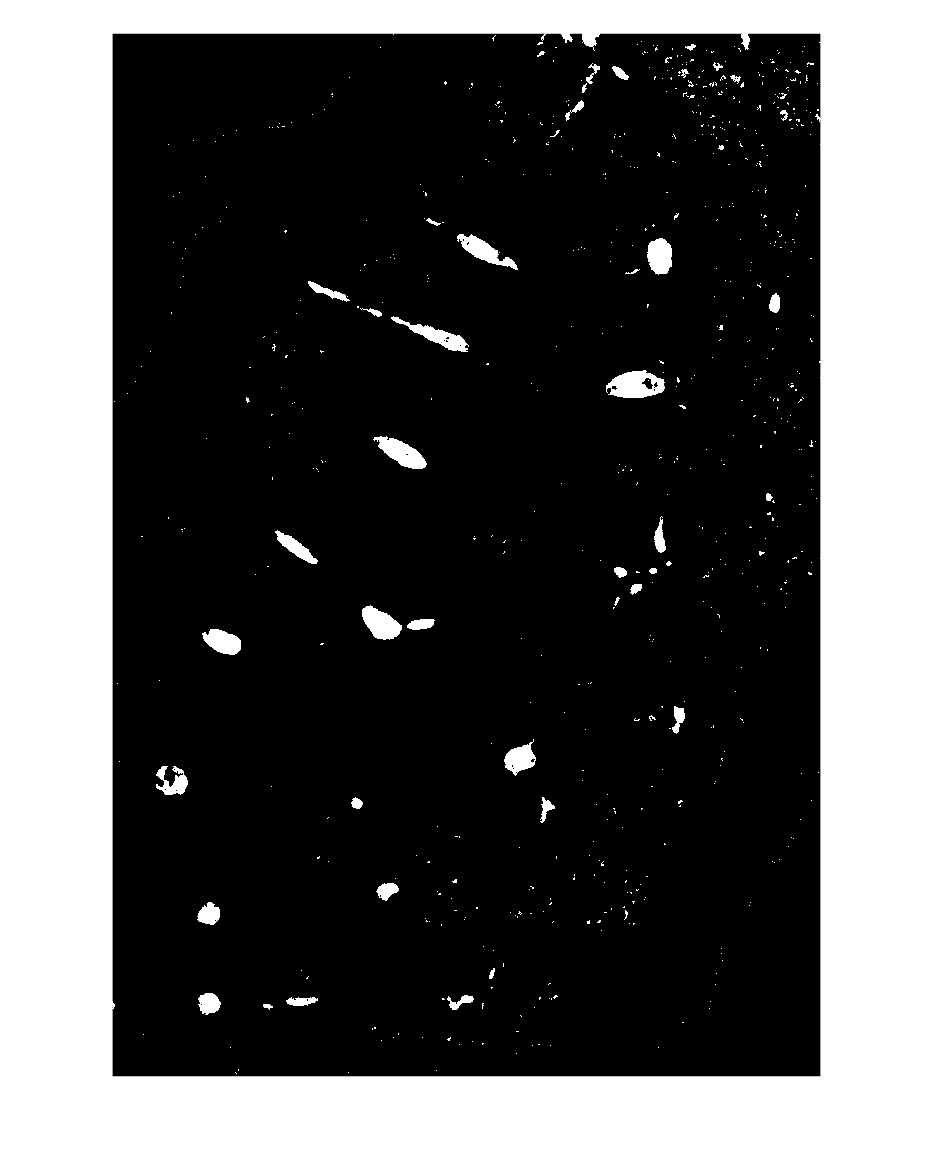

vessel_mask_new = vessel_mask & ~edge_mask;
imshow(vessel_mask_new(:,:,plane));

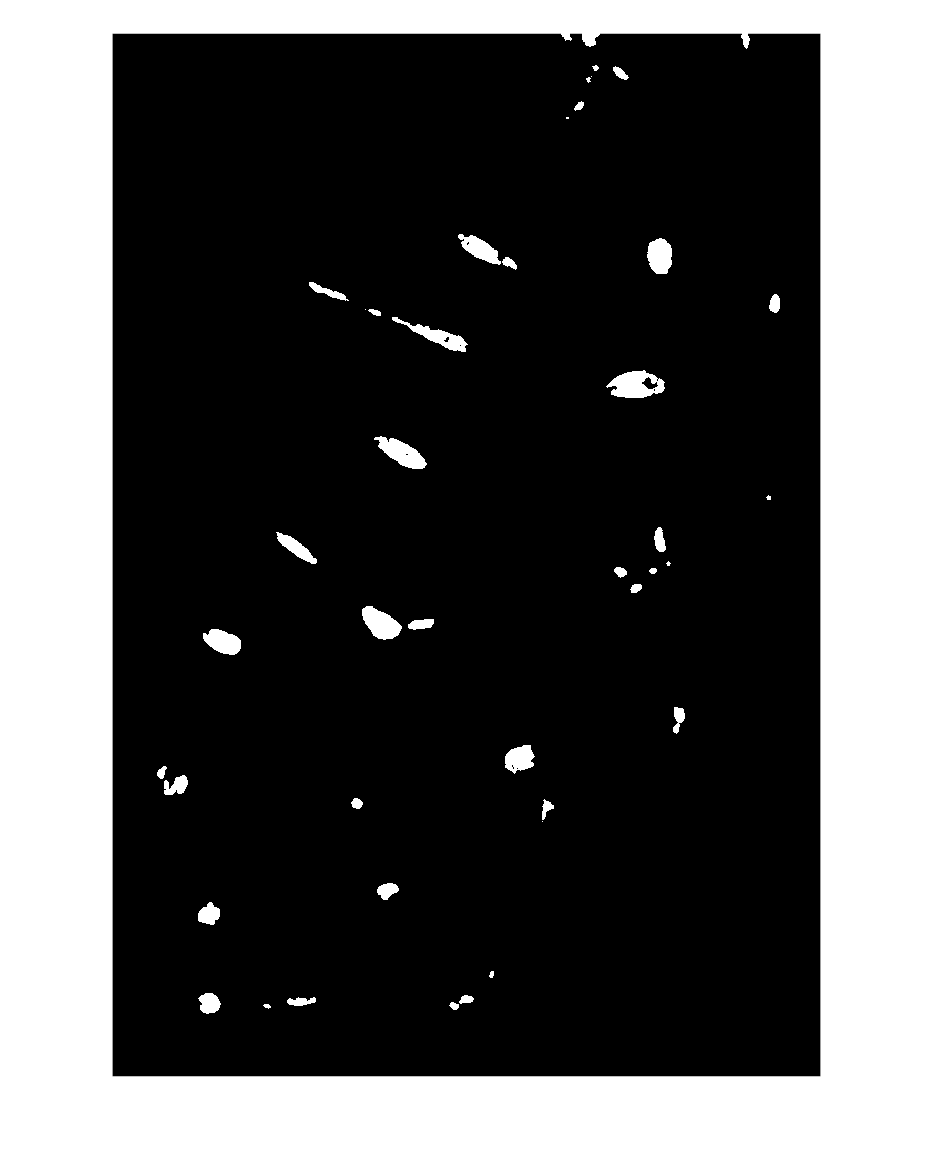

% remove sinusoid, etc.
vessel_mask_open = imopen(vessel_mask_new, strel('sphere', 4));
imshow(vessel_mask_open(:,:,plane));

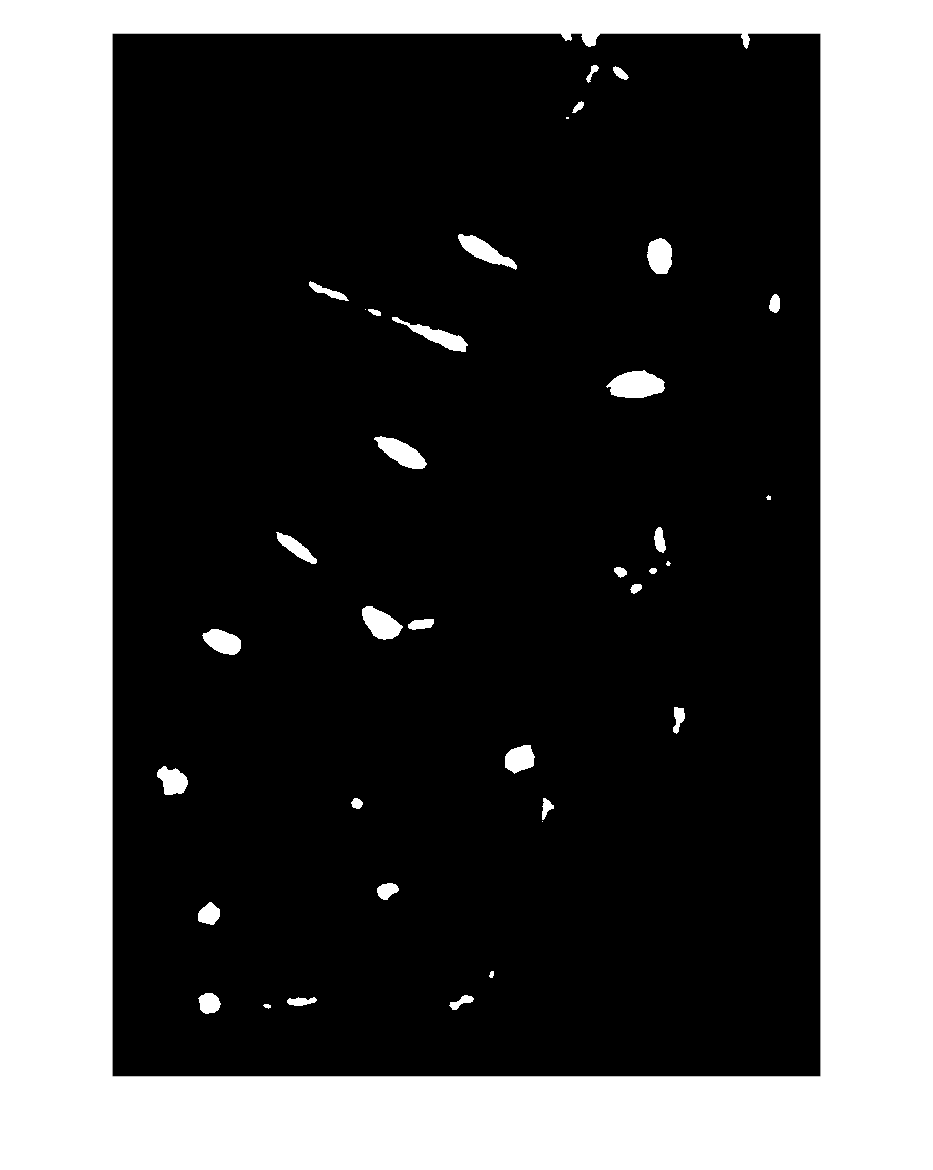

% remove small object in vessel
vessel_mask_close = imdilate(vessel_mask_open, strel('sphere', 4));
vessel_mask_close = imdilate(vessel_mask_close, strel('sphere', 4));
vessel_mask_close = imdilate(vessel_mask_close, strel('sphere', 4));
vessel_mask_close = imerode(vessel_mask_close, strel('sphere', 4));
vessel_mask_close = imerode(vessel_mask_close, strel('sphere', 4));
vessel_mask_close = imerode(vessel_mask_close, strel('sphere', 4));
imshow(vessel_mask_close(:,:,plane));

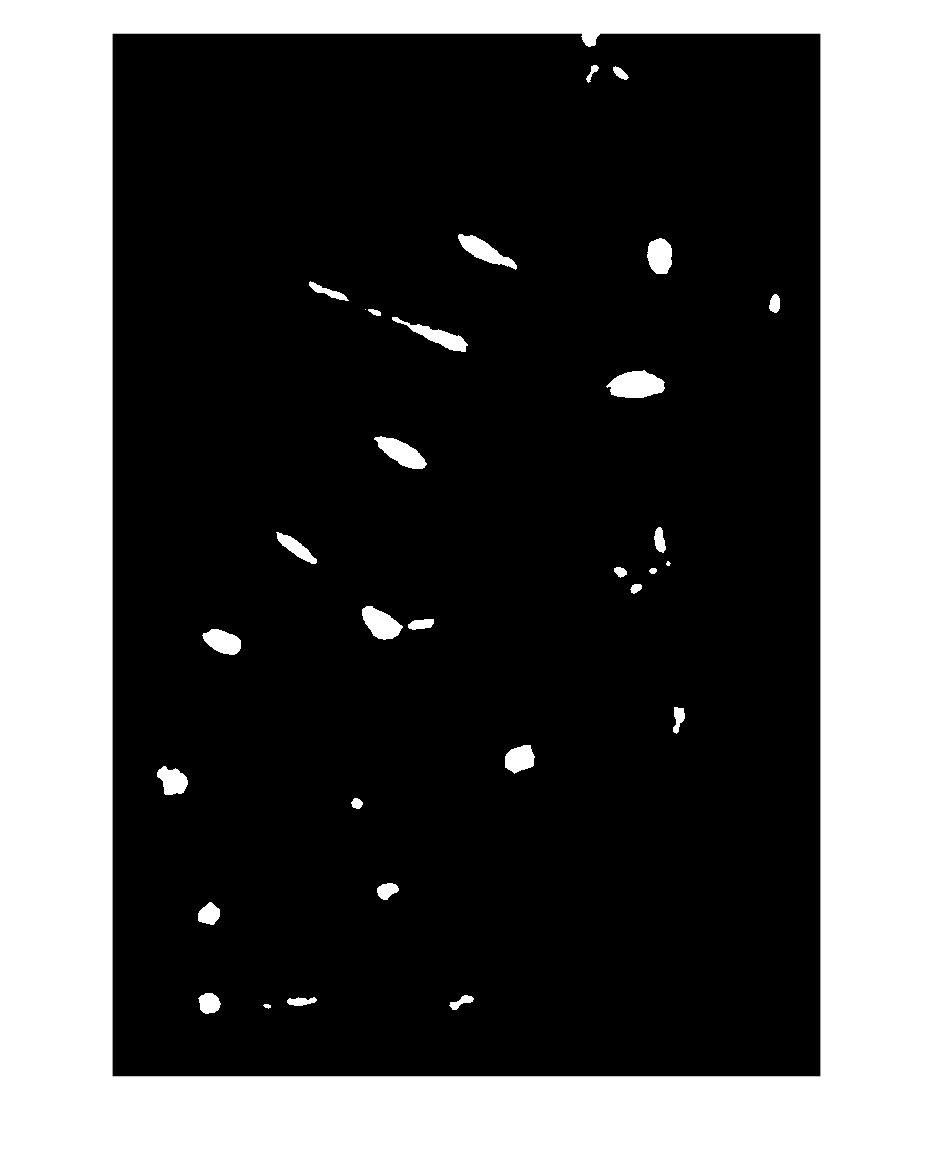

% remove non-connected mask, etc.
[L, num] = bwlabeln(vessel_mask_close);
component_sizes = histcounts(L(L>0), 1:num+1);
[sorted_sizes, sorted_indices] = sort(component_sizes, 'descend');
threshold = 30000;
num_large_mask = sum(sorted_sizes >= threshold);
large_mask = zeros(size(L), 'like', L);
for i = 1:num_large_mask
    large_mask(L == sorted_indices(i)) = i;
end
imshow(large_mask(:,:,plane));

[y, x, z, c] = size(multichannel);
multichannel_new = zeros([y, x, z, 3], 'like', multichannel);
multichannel_new(:, :, :, 1) = nucleus;
multichannel_new(:, :, :, 2) = cellular;
multichannel_new(:, :, :, 3) = large_mask;
% export4d(multichannel_new, 3, folder, outname_temp, extension);

% manual annotation
central = [2,5,7,8,12,14,17];
portal = [1,3,4,9,10,11,13,15,16,18];
artifact = [6];

assert(numel(portal) + numel(central) + numel(artifact) == num_large_mask);
central_mask = zeros(size(L), 'like', L);
portal_mask = zeros(size(L), 'like', L);
for i = central
    central_mask = central_mask | (large_mask == i);
end
for i = portal
    portal_mask = portal_mask | (large_mask == i);
end

[y, x, z, c] = size(multichannel);
multichannel_new = zeros([y, x, z, 4], 'like', multichannel);
multichannel_new(:, :, :, 1) = nucleus;
multichannel_new(:, :, :, 2) = cellular;
multichannel_new(:, :, :, 3) = central_mask;
multichannel_new(:, :, :, 4) = portal_mask;
export4d(multichannel_new, 4, folder, outname, extension);

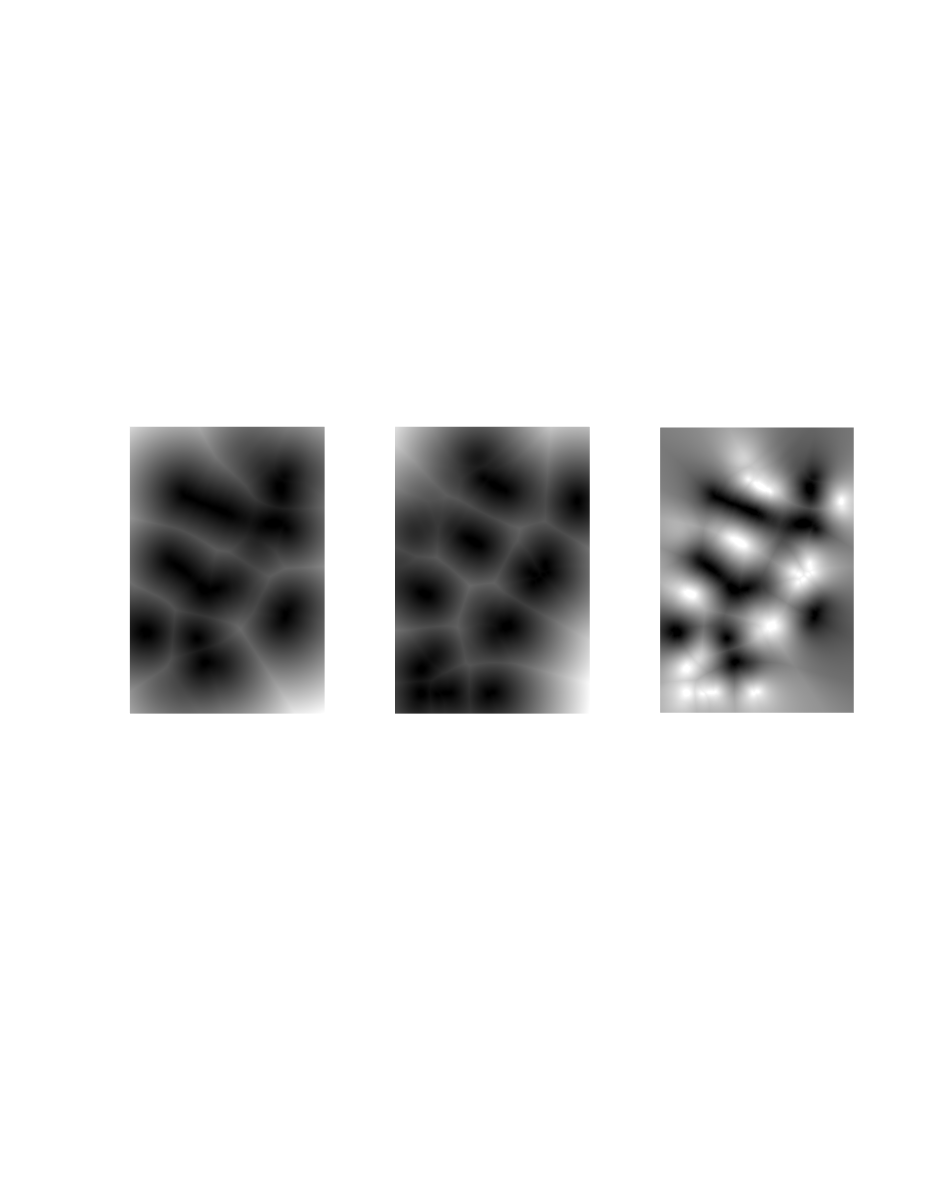

% define zonation by distance ratio
central_distance = round(bwdist(central_mask));
portal_distance = round(bwdist(portal_mask));
distance_ratio = central_distance ./ (central_distance + portal_distance);
subplot(1,3,1), imshow(central_distance(:,:,plane), []);
subplot(1,3,2), imshow(portal_distance(:,:,plane), []);
subplot(1,3,3), imshow(distance_ratio(:,:,plane), []);

scaled_ratio = distance_ratio * 65535;

[y, x, z, c] = size(multichannel);
multichannel_new = zeros([y, x, z, 7], 'like', multichannel);
multichannel_new(:, :, :, 1) = nucleus;
multichannel_new(:, :, :, 2) = cellular;
multichannel_new(:, :, :, 3) = central_mask;
multichannel_new(:, :, :, 4) = portal_mask;
multichannel_new(:, :, :, 5) = central_distance;
multichannel_new(:, :, :, 6) = portal_distance;
multichannel_new(:, :, :, 7) = scaled_ratio;
% export4d(multichannel_new, 7, folder, outname_final, extension);